# GLM Analysis in Homer3 Toolbox

This livescript will demonstrate how to perform GLM analysis using Homer3 toolbox. The following analysis steps will be performed:

## Loading SNIRF Data Files

First, the SNIRF data will be loaded from [Shared Near Infrared Spectroscopy Format](https://fnirs.org/resources/software/snirf/) (SNIRF), which was designed to facilitate sharing and analysing NIRS data. A detailed description of the format can be found [here](https://github.com/fNIRS/snirf/blob/master/snirf_specification.md#snirf-data-format-summary). We will first select a measurement file. 

clear all; close all;

% Select data file to process
p = fileparts(which('simple_pipeline.m'));
while 1
    [fname, pname] = uigetfile([p, '/../SampleData/', '*.snirf'], 'Select snirf file(s)', 'MultiSelect', 'on');
    if fname == 0
        q = menu('You have not selected a data file. Click OK to continue or CANCEL to quit', ...
            {'OK','CANCEL'});
        if q==2
            return
        end
    else
        break;
    end
end

% Load raw intensity signals and metadata into data_nirs 
if iscell(fname) 
    data_nirs = cell(1, numel(fname));
    for fi = 1:numel(fname)
        data_nirs{fi} = SnirfClass([pname, fname{fi}]); 
    end
else
    data_nirs = {SnirfClass([pname, fname])}; 
end


%
% We will now proceed to work with just one measurement data, which we will 
% call _acquired. _
acquired = data_nirs{1};

% The _acquired _Snirf data object contains both raw intensity signals for each 
% wavelength and metadata, such as stimuli information, probes source/detector 
% geometry, measurement date and time, etc. We will now work on the intensity 
% signals and, for that, we save a copy of it in the _intensity_nirs_ variable. 
% It's important to note that just assigning "acquired.data" data structure to 
% _intensity_nirs _ variable will only point to the data in _acquired _data object. 
% This means that any further modifications that we do on _intensity_nirs_ will 
% also be done on the data contained in _acquired. _To prevent this from happening, 
% we create a copy of it as follows:
intensity_nirs = acquired.data.copy; % raw intensity signals

## Convert Intensities to Optical Densities

We will proceed to convert these signals into optical density (OD) signals. These signals represent the attenuation of the transmitted light $(I_0)$in tissue, as measured by the receivers $(I$), for each wavelength. 


$$OD(t, \lambda)$$
 
$$=-log_{10}$$

$$\left(\frac{I(t,\lambda}{I_0(t,\lambda)}\right)}$$


The computation in Homer3 is as follows:

dod = hmrR_Intensity2OD(intensity_nirs);

## Bandpass Filtering

In a common analysis pipeline, fNIRS data is filtered such that the frequency of the hemodynamic response remains and frequencies of other signal components are filtered out. Although there are different opinions on the best filter cutoffs for estimating the hemodynamic response, most researchers filter out frequencies above 0.1 Hz ([Pinti et al., 2018](https://www.frontiersin.org/articles/10.3389/fnhum.2018.00505/full)) in the healthy adult population. We will additionally filter frequencies below 0.01 Hz, and we will do so by means of a bandpass filter.

dodFilt = hmrR_BandpassFilt(dod, 0.00, 0.5);
% Optical densities to concentrations
% Once our data has been filtered, we compute the concentration changes in O2Hb 
% and HHb by means of the Modified Lambert-Beer Law <https://iopscience.iop.org/article/10.1088/0031-9155/33/12/008 
% (Delpy et al., 1988)>.  This conversion requires the user to insert ppf (partial 
% pathlength factor) values corresponding to each wavelength. These are age and 
% wavelength specific. Here we use 6.06.

dhbFilt = hmrR_OD2Conc(dodFilt, acquired.probe, [1, 1]);

## **GLM analysis**

After performing basic data preprocessing steps, we will proceed with the GLM analysis. GLM stands for General Linear Model. In GLM analysis, a reference function, which consists of a linear combination of regressors, is fitted to the time course of each channel. The design matrix for the GLM reference function is created by convolving the boxcar function (boxcar time course acquires values of 1 when the condition is *on _and 0 when the condition is* off_) with the hemodynamic response function. 

We will use _hmrR_GLM _function to run the GLM. Below, we set the parameters for the function. Please refer to Homer3 function documentation to see an explixit explanation of these parameters 

trange = [-2 15];
glmSolveMethod = 1; % Ordinary least squares for inverting design matrix
idxBasis = 2; % Modified gamma function for modeling HRF
paramsBasis = [0.1 3.0 1.8 3.0]; % Parameters to model the shape of HRF (recommended values)

In addition, various other regressors can be added to the model. For example, Homer3 allows regressing Short Separation Channels (SSC), model drifts and auxiliary signals. To enable these regressors, we will specify some more parameters. Specifically, the drift order will be set to 3. Since the SSC were included in the set-up of an example measurement used here, we will set the SSC threshold to 1 cm distance.

driftOrder = 3; % How many drift regressors to use (polynomial order)
rhoSD_ssThresh = 10; % Threshold for SSC channels, in cm
flagNuisanceRMethod = 0; % Regression is performed with the nearest SS channel

% The specified parameters can now be used to run the GLM.

stim = acquired.stim;
probe = acquired.probe;
[data_yavg, data_yavgstd, nTrials, data_ynew, data_yresid, data_ysum2, beta_blks, yR_blks, hmrstats] = ...
    hmrR_GLM(dhbFilt, stim, probe, [], [], [], [], trange, glmSolveMethod, idxBasis, paramsBasis,...
    rhoSD_ssThresh, flagNuisanceRMethod, driftOrder, []);

## Plot Final Results in a Graph

Displaying NIRS-data is typically done by plotting both the average changes of oxy- and deoxyhemoglobin in time. Here, we plot the resulting average * on HbO and HbR signals Extract plot data from output of last function 

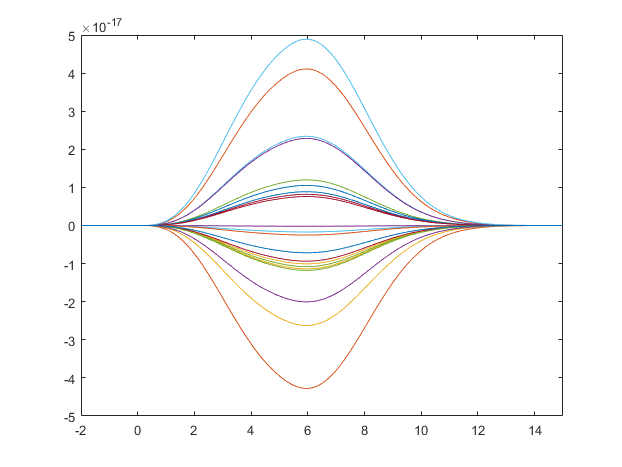

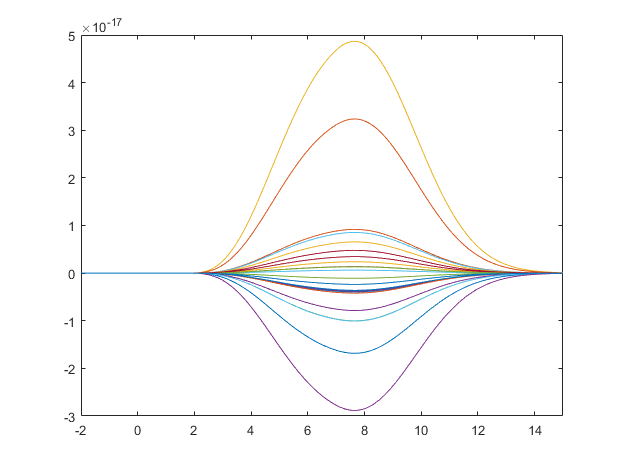

% These are plot figure positioning parameters
px      = .01;
py      = .30;
sx      = .30;
sy      = .40;
xstep   = .15;

% Now plot the GLM processed block average 
tAvg = data_yavg.time;
yAvg = data_yavg.GetDataTimeSeries('reshape');
nChannels = size(yAvg,3);
channels = 1:nChannels;
hbPlotNames = {'HbO ', 'HbR ', 'HbT '};
hbType   = [1, 2, 3];
for iHb = 1:length(hbType)
    figure('menubar','none', 'numbertitle','off', 'name',[hbPlotNames{iHb}, 'Concentration Block Average'], ...
        'units','normalized','position',[px, py, sx, sy]);
    px = px + xstep;
    for iCh = channels
        plot(tAvg, yAvg(:, hbType(iHb), channels(iCh)));
        hold on;
    end
    xlim([min(tAvg), max(tAvg)]);
    hold off;
    pause(1)
end

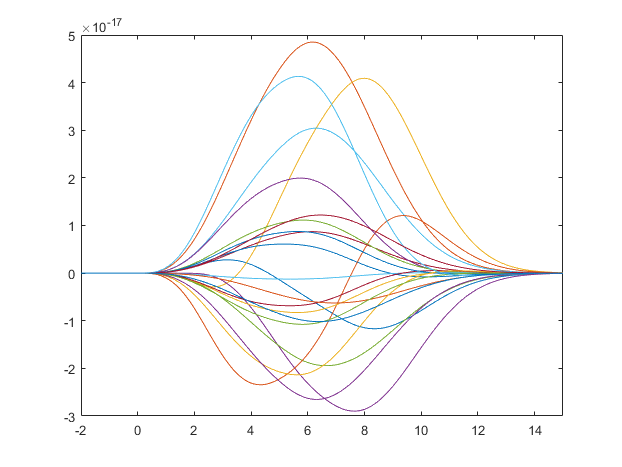

xlim([min(tAvg), max(tAvg)]);
hold off;